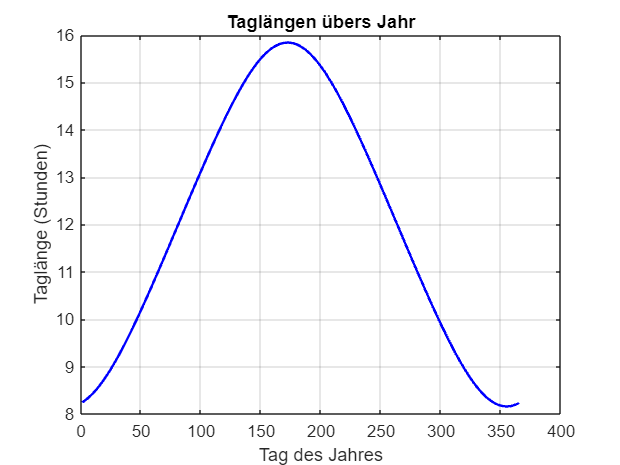

%% Parameter und Grundeinstellungen
phi = 48; % Geografische Breitengrad Muc
specific_days = [80, 172, 266, 355]; % 21. März, 21. Juni, 21. September, 21. Dezember
tage = 1:365; % Alle Tage des Jahres
P_max = 200; % Maximale Leistung der Solaranlage in W/m²(1m² groß?)

%% Berechnung der Taglängen
taglaengen = zeros(size(tage));

for i = 1:length(tage)
    delta = berechne_deklination(tage(i));
    try
        [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta);
        taglaengen(i) = sonnenuntergang - sonnenaufgang;
    catch
        taglaengen(i) = 0; % Keine Sonne (z. B. Polarnächte)
    end
end

% Plot der Taglängen übers Jahr
figure;
plot(tage, taglaengen, 'b', 'LineWidth', 1.5);
title('Taglängen übers Jahr');
xlabel('Tag des Jahres');
ylabel('Taglänge (Stunden)');
grid on;


%% Berechnung der Energie für horizontale Solaranlage
E_horizontal_spezifisch = zeros(size(specific_days));
E_horizontal_gesamt = 0;

for doy = 1:365
    delta = berechne_deklination(doy);
    try
        [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta);
        zeiten = linspace(sonnenaufgang, sonnenuntergang, 100);
        P_t = zeros(size(zeiten));
        for i = 1:length(zeiten)
            alpha = berechne_hoehenwinkel(phi, delta, berechne_stundenwinkel(zeiten(i)));
            P_t(i) = max(0, P_max * sind(alpha)); % Leistung für horizontale Anlage
        end
        E_tag = trapz(zeiten, P_t); % Energie durch numerische Integration
        E_horizontal_gesamt = E_horizontal_gesamt + E_tag;
        
        if ismember(doy, specific_days)
            E_horizontal_spezifisch(specific_days == doy) = E_tag;
        end
    catch
        % keine Energie
    end
end

%% Berechnung der Energie für vertikal (Süden ausgerichtet)
E_vertikal_spezifisch = zeros(size(specific_days));
E_vertikal_gesamt = 0;

for doy = 1:365
    delta = berechne_deklination(doy);
    try
        [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta);
        zeiten = linspace(sonnenaufgang, sonnenuntergang, 100);
        P_t = zeros(size(zeiten));
        for i = 1:length(zeiten)
            alpha = berechne_hoehenwinkel(phi, delta, berechne_stundenwinkel(zeiten(i)));
            azimut = berechne_azimut(phi, delta, alpha);
            
            if alpha > 0 && abs(azimut) <= 90
                cos_theta = max(0, sind(alpha) * cosd(azimut));
            else
                cos_theta = 0;
            end
            
            P_t(i) = max(0, P_max * cos_theta); % Leistung für vertikale Anlage
        end
        E_tag = trapz(zeiten, P_t); % Energie durch numerische Integration
        E_vertikal_gesamt = E_vertikal_gesamt + E_tag;
        
        if ismember(doy, specific_days)
            E_vertikal_spezifisch(specific_days == doy) = E_tag;
        end
    catch
        % Keine Energie
    end
end

%% Ergebnisse anzeigen
% Spezifische Tage und Energie (horizontal und vertikal)
tage_labels = {'21. März', '21. Juni', '21. September', '21. Dezember'};
energie_tabelle = table(...
    tage_labels', ...
    E_horizontal_spezifisch', ...
    E_vertikal_spezifisch', ...
    'VariableNames', {'Datum', 'Energie_Horizontal (Wh)', 'Energie_Vertikal (Wh)'});

% Tabelle anzeigen
disp('Energie an spezifischen Tagen:');

Energie an spezifischen Tagen:


disp(energie_tabelle);

          Datum          Energie_Horizontal (Wh)    Energie_Vertikal (Wh)
    _________________    _______________________    _____________________

    {'21. März'     }            1009.7                         0        
    {'21. Juni'     }            1758.7                    75.707        
    {'21. September'}            990.91                         0        
    {'21. Dezember' }            339.24                         0        




disp('Gesamte Jahresenergie:');

Gesamte Jahresenergie:


disp(['Horizontale Anlage: ', num2str(E_horizontal_gesamt), ' Wh']);

Horizontale Anlage: 377675.015 Wh


disp(['Vertikale Anlage: ', num2str(E_vertikal_gesamt), ' Wh']);

Vertikale Anlage: 5772.9621 Wh



%% Funktionen

% Funktion zur Berechnung der Deklination

function delta = berechne_deklination(doy)
    delta = 23.45 * sind((360 / 365) * (doy + 284));
end

% Berechnung des Stundenwinkels
function H = berechne_stundenwinkel(t)
    H = 15 * (t - 12);
end

% Berechnung des Höhenwinkels
function alpha = berechne_hoehenwinkel(phi, delta, H)
    alpha = asind(sind(phi) * sind(delta) + cosd(phi) * cosd(delta) * cosd(H));
end

% FBerechnung des Azimuts
function azimut = berechne_azimut(phi, delta, alpha)
    azimut = acosd((sind(delta) - sind(alpha) * sind(phi)) / (cosd(alpha) * cosd(phi)));
end

% Berechnung von Sonnenaufgang und Sonnenuntergang
function [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta)
    sonnenaufgang = fzero(@(t) sind(phi) * sind(delta) + cosd(phi) * cosd(delta) * cosd(15 * (t - 12)), [0, 12]);
    sonnenuntergang = fzero(@(t) sind(phi) * sind(delta) + cosd(phi) * cosd(delta) * cosd(15 * (t - 12)), [12, 24]);
end

